Provides an optimal least squares filter to compensate for chromatic dispersion.

Takes as paremeters the sample rate, the chromatic dispersion factor D, the fibre distance z, 

the laser wavelength lambda (l) 

## Filter

Interpolation [decimation] by the integer factor L > 1 requires an upsampler [a downsampler] and an anti-imaging [anti-aliasing]

filter GTX(exp(jωT )) [GRX (exp(jωT ))]. These filters usually have lowpass characteristics with a roll-off of 0 < ρ < 1 leading

to a stopband edge at ωsT = π (1+ρ)/L

Current pulse shaping: L = 8, ρ = 0.2 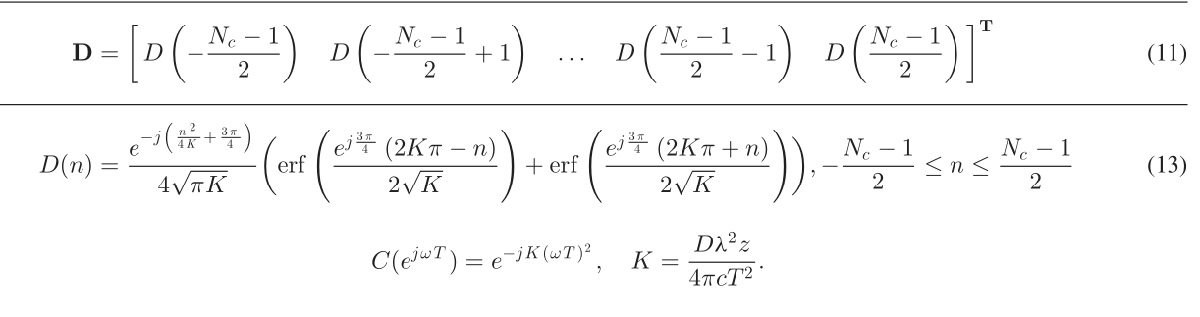

function OLS_FIR = OLS_filter(sample_rate,D,z,l)

T = 1/sample_rate;
c = 299792458; % m/s

N = 2*floor((D*z*l^2)/(2*c*T^2)) + 1;

K = (D*z*l^2)/(4*pi*c*T^2);

n = (-floor(N/2):floor(N/2));
% Assumes full bandwidth from -pi to pi, can be reduced
         
%D_hat = exp(-1j.*((n.^2)/(4*K)+3*pi/4))/(4*sqrt(pi*K)).*(...
%       erfi(exp(3j*pi/4)*(2*K*pi-n/(2*sqrt(K))))...
%       +erfi(exp(3j*pi/4)*(2*K*pi+n/(2*sqrt(K))))...
%       );
   
D_n1 = exp(-1j*3*pi/4)*exp(-1j.*(n.^2)/(4*K))/(4*sqrt(pi*K));   

D_n2 = erfi((exp(1j*3*pi/4)*2*K*pi/(2*sqrt(K)))-(exp(1j*3*pi/4)/(2*sqrt(K))).*n);

D_n3 = erfi((exp(1j*3*pi/4)*2*K*pi/(2*sqrt(K)))+(exp(1j*3*pi/4)/(2*sqrt(K))).*n);

OLS_FIR = D_n1.*(D_n2+D_n3); 

end